xsyms t

%part1
m=0.85;
fc=250;
Ac=1;
t0=0.15;
x(t)=piecewise(0<=t<t0/3,0.5,t0/3<=t<(2*t0)/3,-1,0);
xc(t)=AM_module(x,fc,Ac,m) 

$$xc(t) = \left\{ \begin{array}{cl} \frac{57\,\cos\left(500\,\pi \,t\right)}{40} & \text{ if }t\in \left[0,\frac{1}{20}\right)\\ \frac{3\,\cos\left(500\,\pi \,t\right)}{20} & \text{ if }t\in \left[\frac{1}{20},\frac{1}{10}\right)\\ \cos\left(500\,\pi \,t\right) & \mathrm{otherwise} \end{array}\right.$$

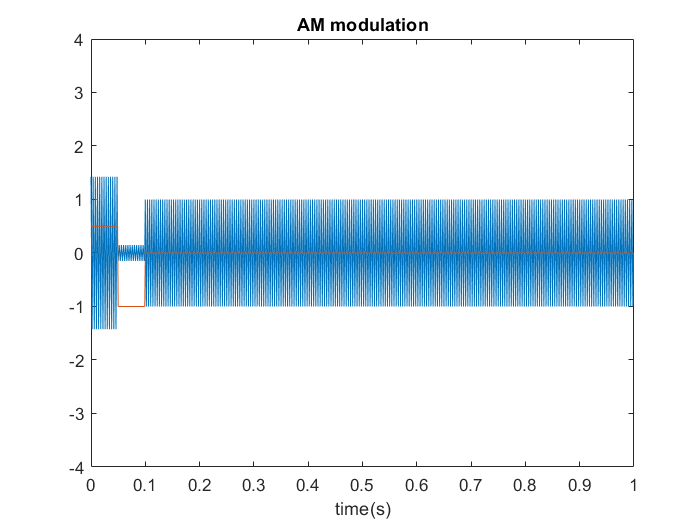


fs=1000;
t1=0:1/fs:1-1/fs;
t2=0:1/fs:1-1/fs;

xc_sample=double(xc(t1));
x_sample=double(x(t2));
plot(t1,xc_sample,t2,x_sample)
ylim([-4,4])
title('AM modulation');
xlabel('time(s)');

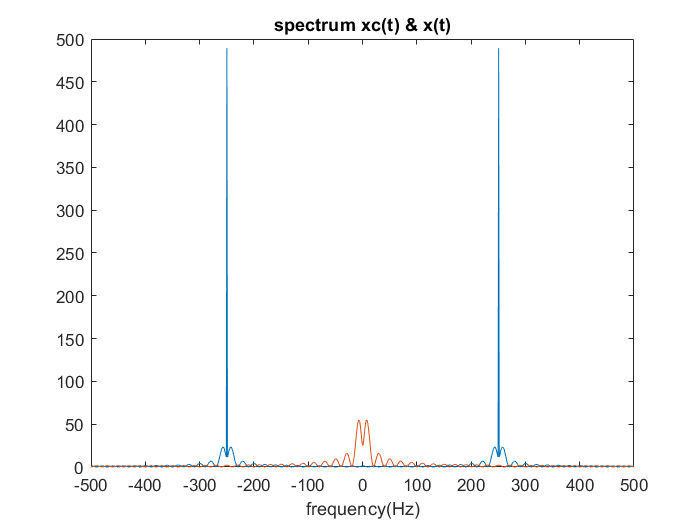



Xf=fftshift(fft(x_sample));
XCf=fftshift(fft(xc_sample));
f1=fs/2*linspace(-1,1,fs);
f2=fs/2*linspace(-1,1,fs);

figure
plot(f1,abs(XCf),f2,abs(Xf))
title('spectrum xc(t) & x(t)');
xlabel('frequency(Hz)');


power_xt=(int(x(t)^2,0,0.15))/0.15

$$power\_xt = \frac{5}{12}$$

t_sidebands=((Ac*0.85)^2)*power_xt/2

$$t\_sidebands = \frac{289}{1920}$$

total_power=Ac/2+t_sidebands

$$total\_power = \frac{1249}{1920}$$

efficiency=t_sidebands/total_power

$$efficiency = \frac{289}{1249}$$

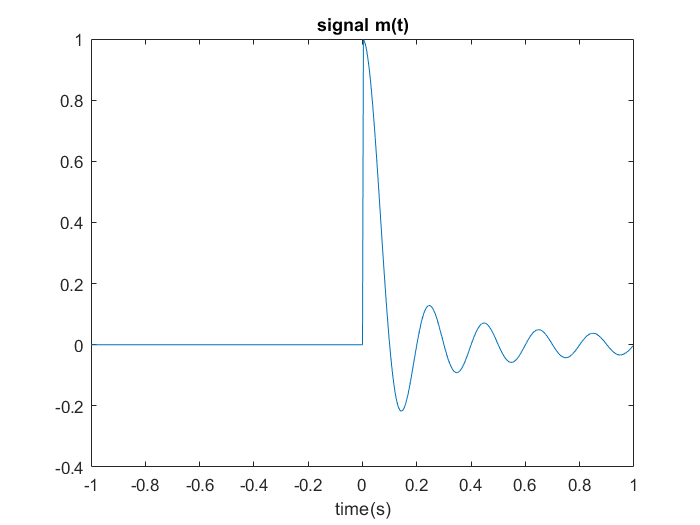

%part2
x2(t)=piecewise(0<=t<=1,sinc(10*t),0);
fs2=600;
t3=-1:2/fs2:1-2/fs2;
x2_sample=double(x2(t3));
x2_sample(301)=0;
X2f=fftshift(fft(x2_sample));
f3=fs2/2*linspace(-1,1,fs2);

figure
plot(t3,x2_sample)
title('signal m(t)');
xlabel('time(s)');

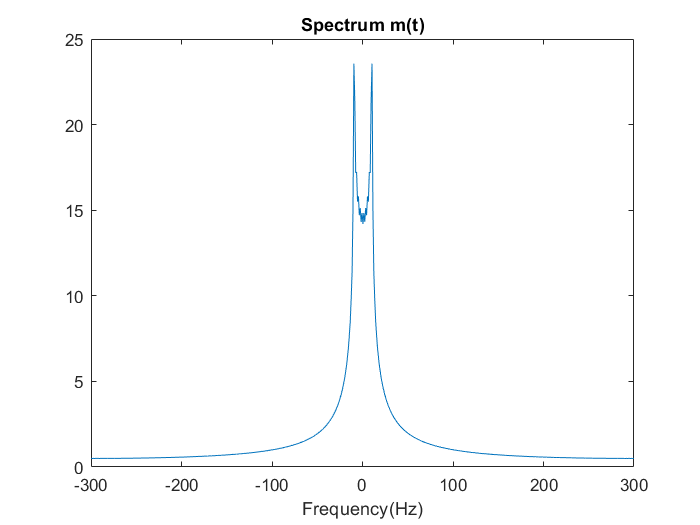


figure
plot(f3,abs(X2f))
title('Spectrum m(t)');             
xlabel('Frequency(Hz)');

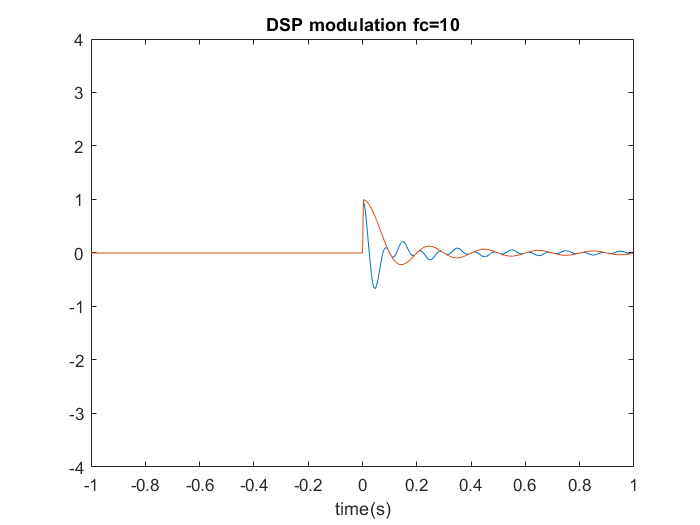



% a 

xc1(t)=DSP_module(x2,10,Ac); 
xc2(t)=DSP_module(x2,50,Ac); 
xc3(t)=DSP_module(x2,100,Ac); 

xc4(t)=DSP_module(x2,600,Ac); 
xc5(t)=DSP_module(x2,1200,Ac); 

xc1_sample=double(xc1(t3));
xc1_sample(301)=0;
xc2_sample=double(xc2(t3));
xc2_sample(301)=0;
xc3_sample=double(xc3(t3));
xc3_sample(301)=0;
XC3f=fftshift(fft(xc3_sample));

xc4_sample=double(xc4(t3));
xc4_sample(301)=0;
xc5_sample=double(xc5(t3));
xc5_sample(301)=0;

figure
plot(t3,xc1_sample,t3,x2_sample)
ylim([-4,4])
title('DSP modulation fc=10');
xlabel('time(s)');

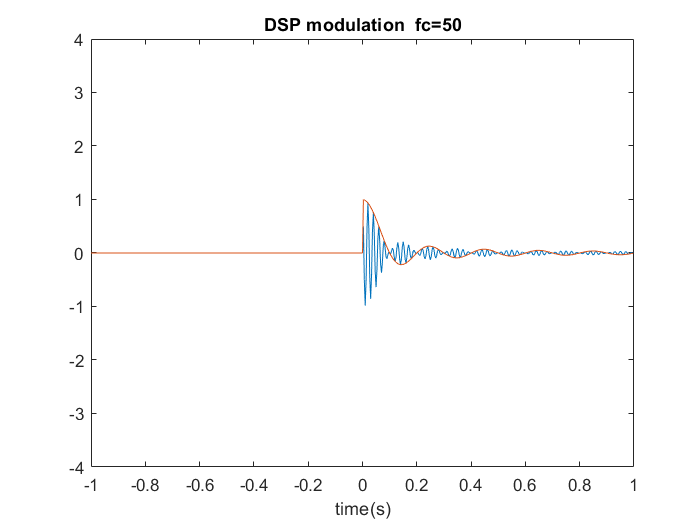


figure
plot(t3,xc2_sample,t3,x2_sample)
ylim([-4,4])
title('DSP modulation  fc=50');
xlabel('time(s)');

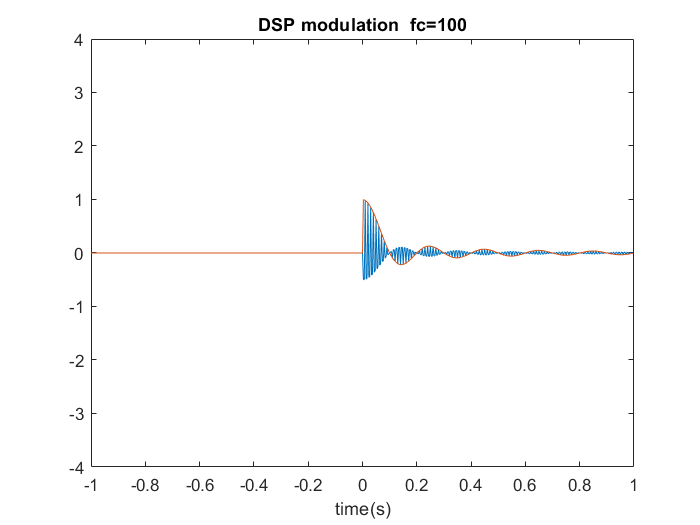


figure
plot(t3,xc3_sample,t3,x2_sample)
ylim([-4,4])
title('DSP modulation  fc=100');
xlabel('time(s)');

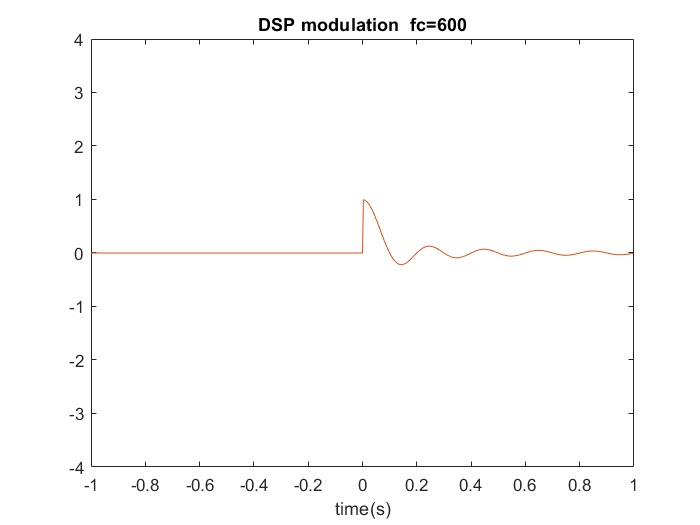


figure
plot(t3,xc4_sample,t3,x2_sample)
ylim([-4,4])
title('DSP modulation  fc=600');
xlabel('time(s)');

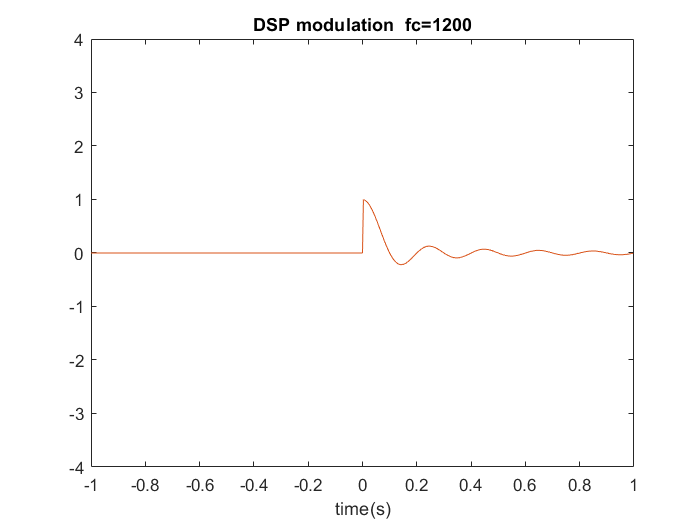


figure
plot(t3,xc5_sample,t3,x2_sample)
ylim([-4,4])
title('DSP modulation  fc=1200');
xlabel('time(s)');

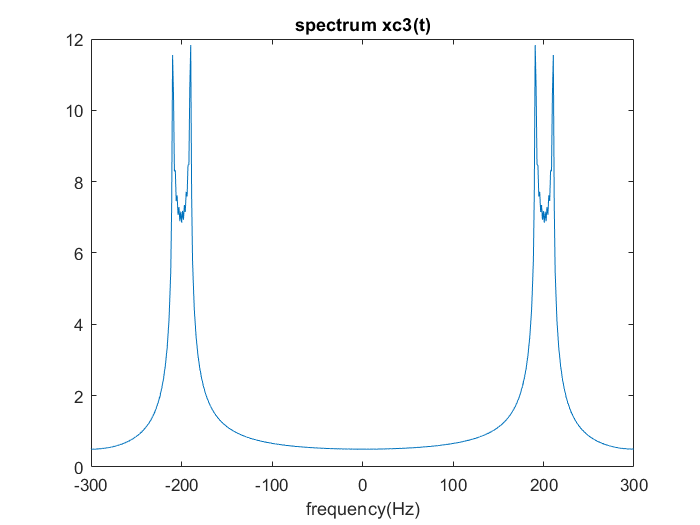



% B

figure
plot(f3,abs(XC3f))
title('spectrum xc3(t)');          
xlabel('frequency(Hz)');

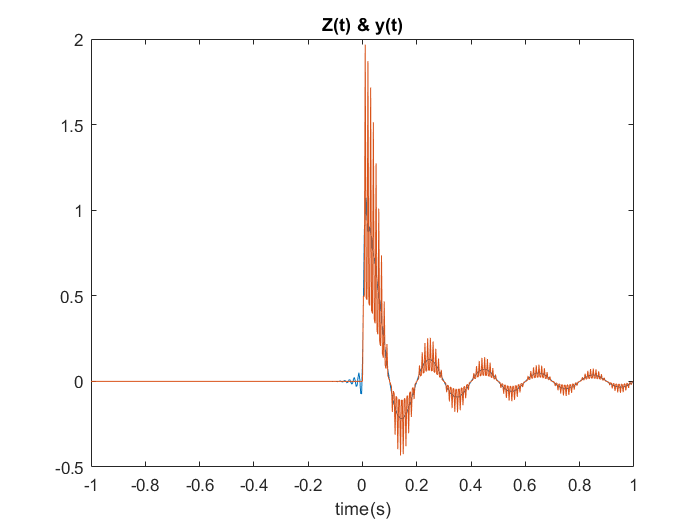



%D


[z,y]=DSP_demodule(xc3_sample,100,Ac,600) ;
Yf=fftshift(fft(y));
Zf=fftshift(fft(z));      

figure
plot(t3,z,t3,y)
title('Z(t) & y(t)');        
xlabel('time(s)');

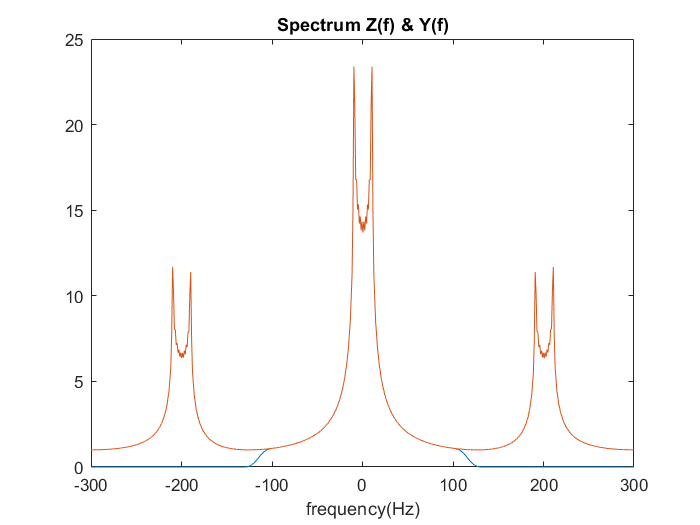



figure
plot(f3,abs(Zf),f3,abs(Yf))
title('Spectrum Z(f) & Y(f)');        
xlabel('frequency(Hz)');

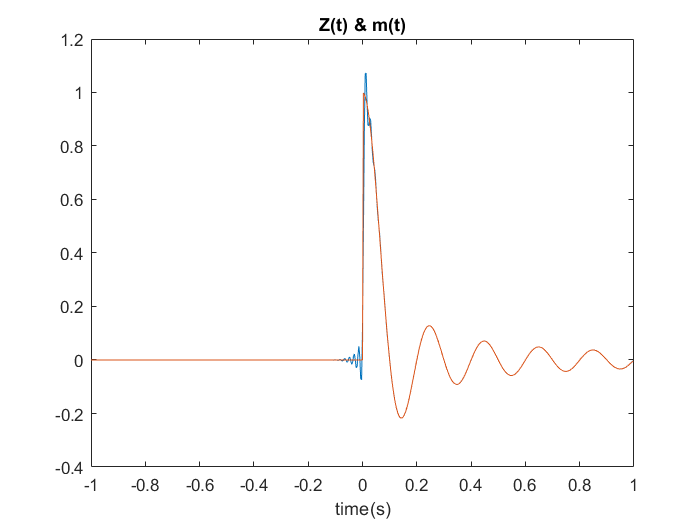


figure                                  
plot(t3,z,t3,x2_sample)
title('Z(t) & m(t)');        
xlabel('time(s)');


immse(z,x2_sample)

ans = 5.7718e-04



% E     I generated a MSE.m function to Variable scrolling fc

fc1=-500:10:500;
Errors= MSE(x2,x2_sample,Ac,fs2) ;

$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(1000\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors = 5.7718e-04

$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(980\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors = 	1.0e+-3 *

    0.5772    0.6644


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(960\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(940\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(920\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(900\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(880\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(860\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(840\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(820\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(800\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(780\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(760\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(740\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(720\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(700\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(680\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(660\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(640\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(620\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(600\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(580\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(560\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(540\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(520\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(500\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(480\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(460\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(440\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(420\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(400\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(380\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(360\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(340\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(320\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(300\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(280\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(260\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(240\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(220\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(200\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(180\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(160\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(140\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(120\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(100\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(80\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(60\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(40\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(20\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(20\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(40\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(60\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(80\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(100\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(120\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(140\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(160\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(180\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(200\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(220\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(240\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(260\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(280\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(300\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(320\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(340\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(360\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(380\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(400\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(420\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(440\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(460\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(480\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(500\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(520\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(540\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(560\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(580\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(600\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(620\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(640\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(660\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(680\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(700\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(720\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(740\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(760\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(780\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(800\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(820\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(840\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(860\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(880\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(900\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(920\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(940\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(960\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(980\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


$$xc\_inLoop(t) = \left\{ \begin{array}{cl} \frac{\cos\left(1000\,\pi \,t\right)\,\sin\left(10\,\pi \,t\right)}{10\,t\,\pi } & \text{ if }t\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Errors =     0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006    0.0006    0.0007    0.0036    0.0112    0.0114    0.0239    0.0114    0.0112    0.0036    0.0007    0.0006    0.0006    0.0005    0.0005    0.0006


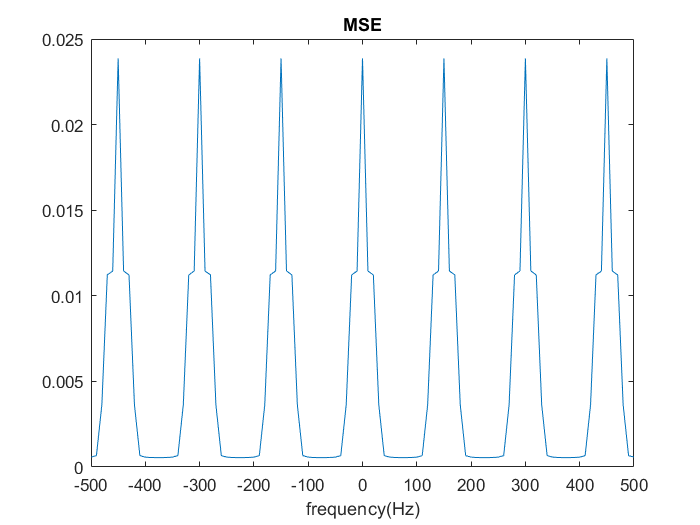

figure
plot(fc1,Errors)
title('MSE')
xlabel('frequency(Hz)')